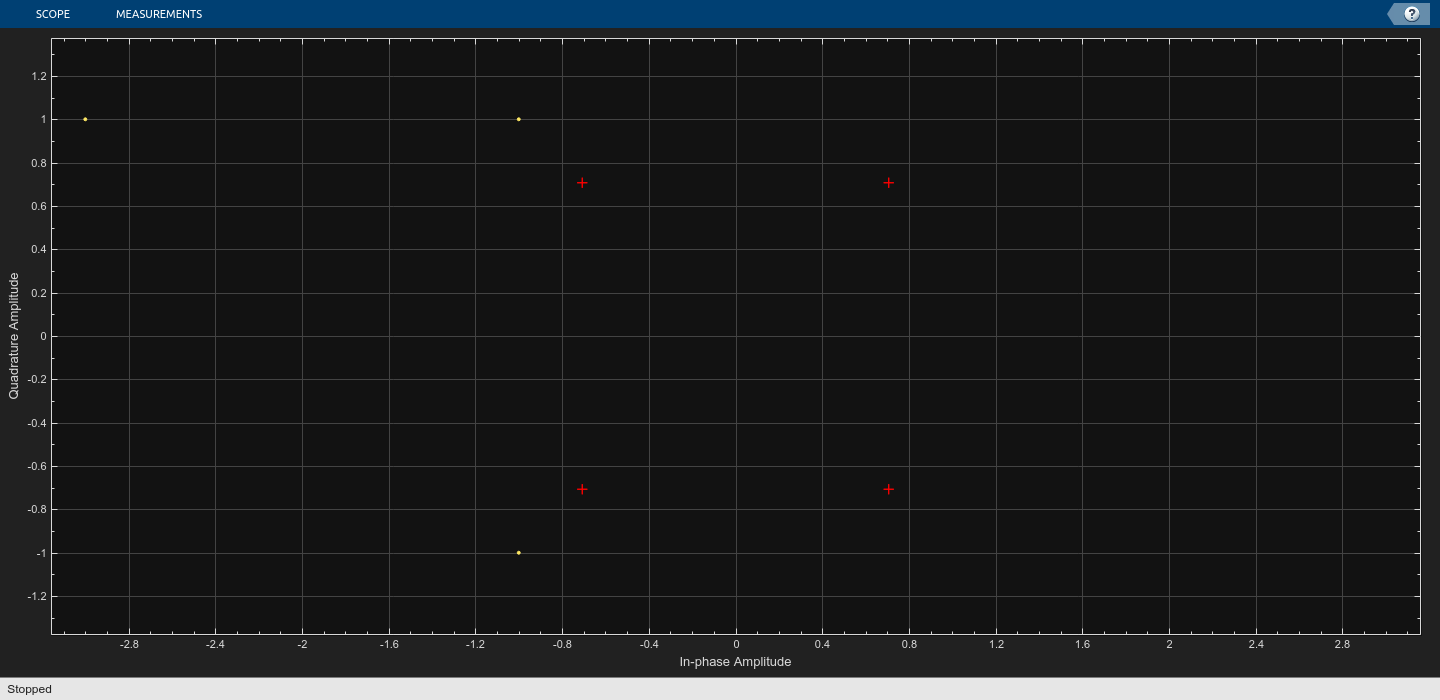

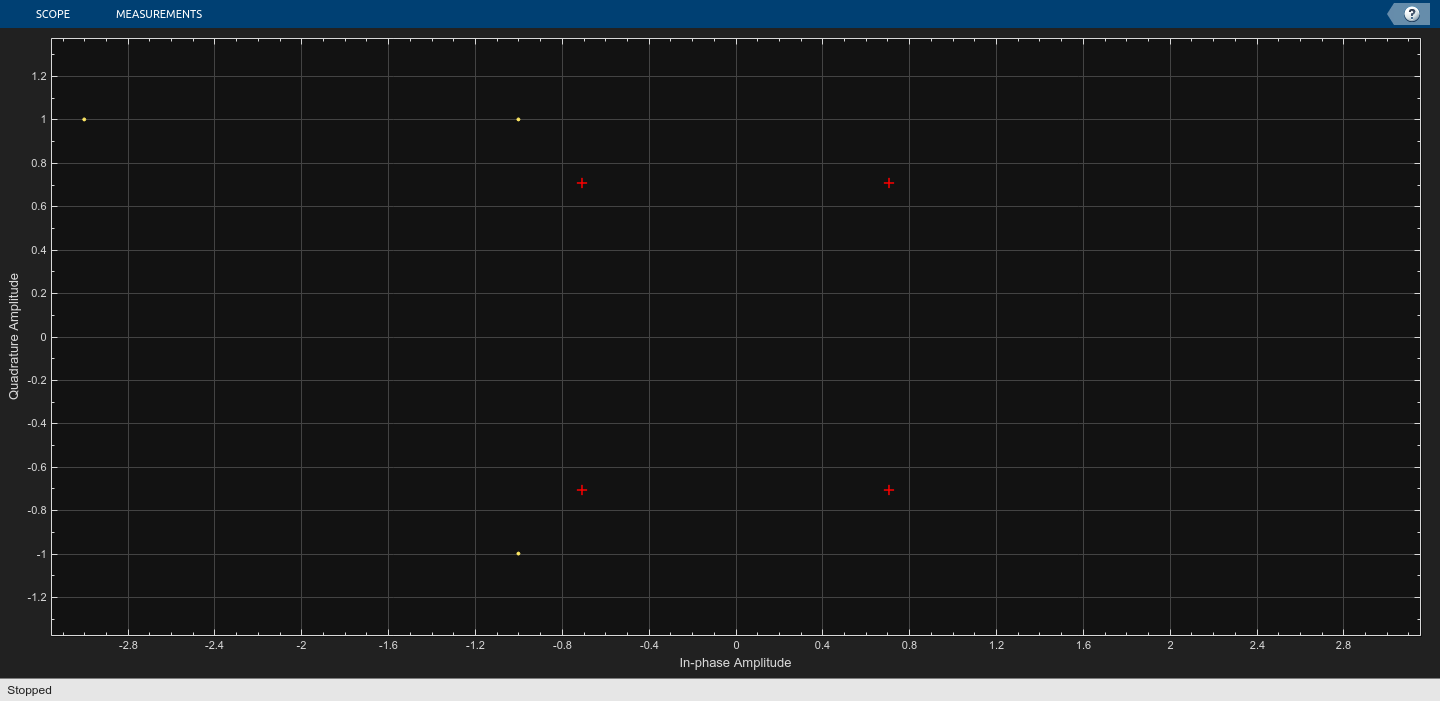

%% sweepAndPlotAllBER.m

%— Configuration 
model     = 'static_mile3';
awgnBlock = [model '/AWGN Channel'];
snr_vals  = -20:10:100;                    % your SNR sweep grid
 
% Preallocate storage
ber_adaptive = zeros(size(snr_vals));
ber_qpsk     = zeros(size(snr_vals));
ber_16qam    = zeros(size(snr_vals));
ber_64qam    = zeros(size(snr_vals));

% Load the model once (but don’t start simulating yet)
load_system(model);

%— Sweep through SNR points
for k = 1:numel(snr_vals)
  % 1) Set AWGN channel SNR
  set_param(awgnBlock, 'SNR', num2str(snr_vals(k)));
  
  % 2) Run the sim, return all To-Workspace outputs in simOut
  simOut = sim(model, 'ReturnWorkspaceOutputs', 'on');
  
  % 3) Grab the last error value from each of your four signals
  ber_adaptive(k) = simOut.err(end);   % your ‘Adaptive’ BER
  ber_qpsk(k)     = simOut.err1(end);  % QPSK BER
  ber_16qam(k)    = simOut.err2(end);  % 16-QAM BER
  ber_64qam(k)    = simOut.err3(end);  % 64-QAM BER
end

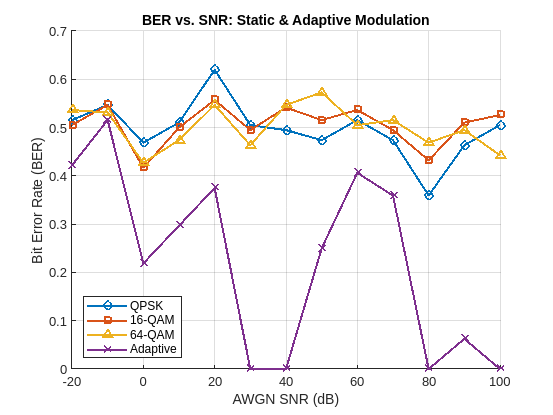


%— Plot all four curves
figure; hold on;
semilogy(snr_vals, ber_qpsk,     '-o','LineWidth',1.5,'DisplayName','QPSK');
semilogy(snr_vals, ber_16qam,    '-s','LineWidth',1.5,'DisplayName','16-QAM');
semilogy(snr_vals, ber_64qam,    '-^','LineWidth',1.5,'DisplayName','64-QAM');
semilogy(snr_vals, ber_adaptive, '-x','LineWidth',1.5,'DisplayName','Adaptive');
grid on;
xlabel('AWGN SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER vs. SNR: Static & Adaptive Modulation');
legend('Location','southwest');